# Fundamentals of Practical Programming

[⇦ Overview](matlab: run("OpenOverview.m"))

Programming involves the efficient use of computational resources to solve problems. Some problems are difficult to formulate as a computer program (e.g., "drive a car") while others are fairly simple (e.g., "approximate a solution to a first order differential equation"). Conveniently for humanity, these do not necessarily correlate with the difficulty of a problem as perceived by humans. Consider trying to "program your computer to identify a photograph of a cat" versus "program your computer to determine an optimal flight path to the moon". Fundamentally, computers are phenomenal at repetition and at performing mathematical calculations, so those are the features we shall be considering primarily throughout this discussion of the fundamentals of programming.  

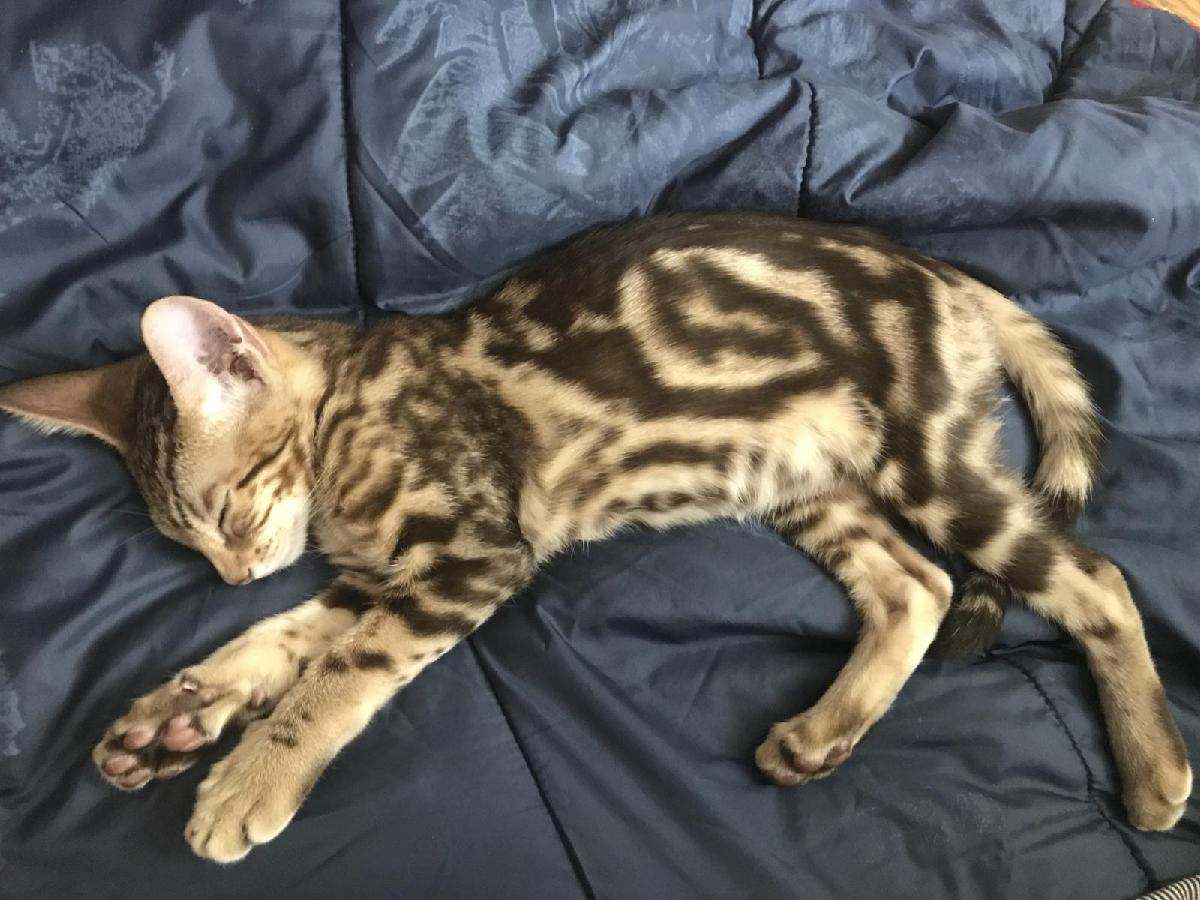                  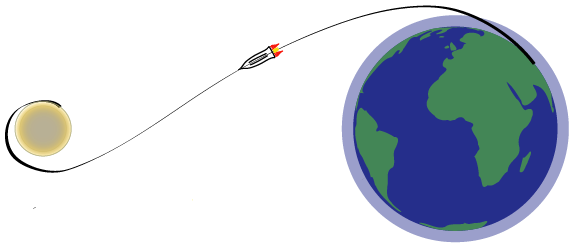

This module will provide you with the basic tools needed to tell computers how to solve problems for you.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB, as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running the code blocks in it.

## Basic Components for Programming

### What is programming?

Computer programming can mean a variety of different things based on context, but for the purposes of this module we will define computer programming as using a pre-defined language to tell a computer to perform particular operations in a given sequence. In some cases, all of the instructions must be provided at once and the computer simply moves on to the next as soon as it has dealt with the previous instruction. In other cases, the programmer can participate more interactively and change their instructions based on intermediate responses by the computer. Over the course of this module you will interact with your computer in both of these ways. 

### Simple Input

In order to program a computer, you need to know what information you have available to start with, such as data, e.g., the days of the week. Run this code block by clicking the    **Run Section** button in the **Live Editor** tab.

["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"]

ans = 1×7 string array
    "Monday"    "Tuesday"    "Wednesday"    "Thursday"    "Friday"    "Saturday"    "Sunday"


Input values are information that are provided to a program before computation, and output values are information that are provided by a program after computation.

 **Reflect**. 

- What do you notice about the output when you run this code? Are the square brackets present in the output? What about the quotation marks? Is there any additional text in the output? What questions does this raise?

- What is the input to this program? Why is the input in square brackets? Do the spaces matter? What about the quotation marks?

This code creates a grouped set of values. The structures related to the note labeling this set as a `1x7 string` will be discussed in the [`Data`](matlab:open('./Data.mlx')) live script. For the moment, consider the `ans = `detail. 

The phrase `ans` is short for `answer` and can be used to refer to the set defined by this code. Type `ans` in the code block below and then run this section. What do you expect?

ans

ans = 1×7 string array
    "Monday"    "Tuesday"    "Wednesday"    "Thursday"    "Friday"    "Saturday"    "Sunday"


It is frequently useful, however, to use more descriptive and unique names that can be attached to collections of data. Run this section. What has changed in the output?

daysOfWeek = ["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"]

daysOfWeek = 1×7 string array
    "Monday"    "Tuesday"    "Wednesday"    "Thursday"    "Friday"    "Saturday"    "Sunday"


### Errors

What happens if you run the code below without the quotation marks around each day?

daysOfWeek = [Monday Tuesday Wednesday Thursday Friday Saturday Sunday]

This code generates an *error*. Different programming languages warn of errors in different ways, but there are some commonalities. One standard is the error code and/or error message. If this is the first time you’ve seen an error message, don’t be intimidated. They are here to help you fix your code. Every programmer, even the most professional and experienced, writes code with errors at times. In a live script like this there is an 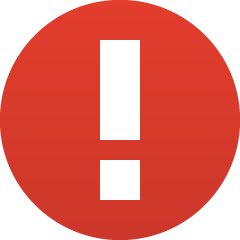 icon at the top left of the window as well as on the right-hand side of the line where the error is located in addition to the red text spelling out the error message. In this case, without the quotation marks, MATLAB is interpreting `Monday` as a programming command that it doesn't recognize rather than as data. 

When you encounter errors, read the error messages and figure out where the error is being generated. Usually, this will allow you to fix the error and continue with your program. In this case, try adding quotation marks around all the words inside of the square brackets like so:

in the code block in line 4. What happens when you run this code? What is the same? What is different?

 **Warning:** You must fix any errors in the code before you can run any of the code that depends on it. In this case, each section is treated independently, but if you try to run all the code in the entire script at once by clicking the   **Run **button in the **Live Editor** tab, no code past this section will run until you fix the error.  

  **Pro-tip**. If you have accidentally run code you didn't mean to run, you can clear all the output in the entire file by clicking the   **Clear all Output** button in the **View** tab, or right-click to bring up the context menu on a particular block of code and select **Clear Output** to clear only the output in that section. 

Not every type of data requires quotation marks to be properly stored, however. Run the code block below:

% How many turkeys did I see each day last week?
numTurkeys = [9 6 8 5 7 9 8]

  **Try**.

- Delete the comment

            and run the code again. What changes?

        2. Add a semicolon to the end of the line of code like so:

            What happens when you run the code now? 

        3. Edit the value corresponding to the third day of the week. Perhaps you saw 0 turkeys on Wednesday? Then run the code again. What changes? Can you tell? Try looking in the Workspace window.

 **Reflect**.

- How should comments be used?

- Can you think of situations where you might want to run code, but suppress the output? 

### Comments 

Programming languages each have a way to mark sections of code as *comments*. Comment sections are ignored entirely by the computer when it works through the rest of the program. Comments should be used to provide information to the human reading a program in a way that adds value. MATLAB uses a % to mark the rest of that line as being a comment. Python uses # similarly, while C comments are any amount of text between /* and */. 

  **Pro-tip**. Programming languages need a way to communicate results to programmers. The simplest version of this is frequently called "standard output" and normally consists of printing the results on the screen. Adding a semicolon at the end of the line in MATLAB tells the computer that you don't want to display the results of that line as standard output. Programming languages also have to store more than one bit of data at a time. Some programming languages share information about what is currently stored and therefore available to be accessed. MATLAB offers this information in the Workspace window on the right. What data is available to you at the moment?

It is also possible to provide data interactively to a computer. Try moving this slider back and forth. Selecting a new value for `wedTurkeys` will run all the code in this section of the script. 

wedTurkeys = 0;
numTurkeys = [9 6 wedTurkeys 5 7 9 8]

All outside information that enters a computer program can be considered input. The input level is where sensors and user interactivity, for instance, can provide information to the system. 

  **Try**. You can run this section of code as usual, but simply moving the slider to set a positive value of `wedTurkeys` will also trigger the section to run. 

- Change the value of `wedTurkeys` to the original value of 8. What happens to `numTurkeys`?

- Change the value of `wedTurkeys` to 3.5. What happens to `numTurkeys`? There is further discussion of storing numbers in code in [Data.mlx](matlab:open('./Data.mlx')).

- Look at the variables in the Workspace. What happened to the original `numTurkeys`?

- Add a comment to this code block explaining what it does.

 **Reflect**. 

- What do you notice about the results when you run this code? What questions does this raise?

- Does the program generate an error if your count involves partial turkeys? Why or why not?

- Can you tell where the section boundary is? Why or why not?

  **Pro-tip**. Notice that the code has line numbers associated with it. The   **Run** command runs each line of code in order from Line 1 until the last line in the script. You can clear the output in the script in the **View** tab by clicking **Clear all Output**.

You have already seen ways to input both textual data and numerical data, but computers can handle many other types of data as well such as images, video, or sound files. What do you think will happen when you run the code below?

% Load an image of the turkeys
picTurkeys = imread("turkeys1.jpg")

picTurkeys = 562×1963×3 uint8 array
picTurkeys(:,:,1) =

  Columns 1 through 1,666

    49    53    60    73    84    80    71    70    58    39    25    22    35    43    34    34    54    68    75    65    64    81   104   128   137   139   142   156   147   114   109   127   147   144   140   137   128   121   119   106    97   101    90    68    48    29    24    30    41    47    55    58    57    55    52    49    51    52    53    50    45    48    60    72    83    98   113   130   125   110    90    43    19    21    26    23    37    42    41    27    31    35    36    38    43    45    43    43    48    49    53    56    54    51    54    59    59    63    64    57    41    25    17    16     8     3     0     3    11    20    31    39    31    17    21    15    20    17     7     4     4    15    31    23    33    37    36    30    18    18    16    16    30    62    84    86    78    70    69    69    69    74    79    75    69    66    58    49    57    61    56    61    

Your computer is just showing you how it actually understands this image file. You can investigate this further in [Arrays.mlx](matlab:open('./Arrays.mlx')).This is a good example of a line of code that is much easier to handle if you suppress the output by adding a semicolon. Don't lose `picTurkeys`, however, because we'll come back to it soon in a human-readable format as well.

## Commands

You also need to tell the computer what to do with the input. For inspiration, consider the simple computer known as a calculator:

4+7
35/65
-2*3.2
sin(pi/2)

Notice that the first three are arithmetic calculations, but the last one is a function that takes a number in radians and calculates the sine.  The final command, `sin(pi/2)`, probably seems very similar to the first three arithmetic problems. They are all just math! If you consider for a moment, though, while you know how to calculate `4+7` or `-2*3.2` or even `35/65` if you had to, you probably do not know how to compute $\sin(\theta)$ for a general value of $\theta$. In fact, it is a significantly more involved calculation with lots of addition, subtraction, multiplication, and division and still will only give you an approximate value. Each function in a programming language is a name for a specific set of instructions that a computer will follow.  

There are a lot of functions that take different types of input. For instance, there are functions that will take the numbers of `picTurkeys` and display the turkey image in a more human-readable format. Try using the command `imshow:`

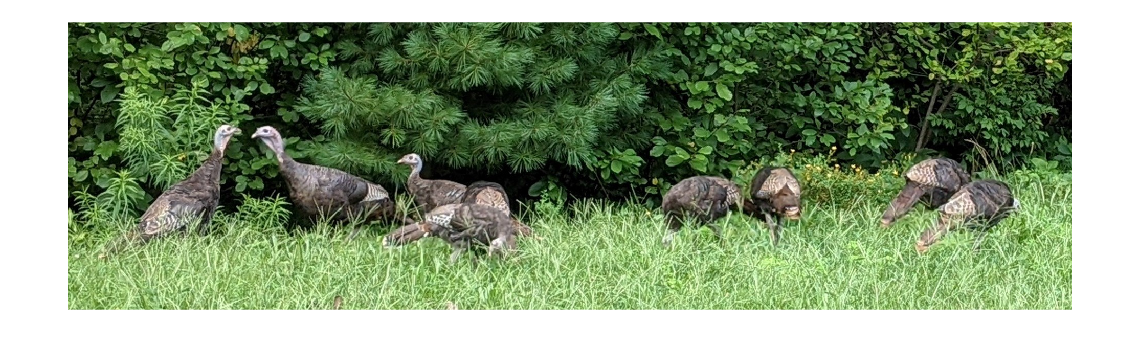

imshow(picTurkeys)

 **Reflect**.

- Does this look more like turkeys to you than the first attempt?

- What other kinds of mathematical functions might you expect to have in a programming language?

- What other kinds of functions might you want to apply to an image?

### Learning More: Documentation

You know that the argument to `sin` could be a number of radians or a number of degrees. The result will be different in each case. Calculators have a setting that tells the device whether to interpret the argument as being in radians or in degrees. Maybe you have run into trouble with this in the past when moving between an engineering or physics class and a mathematics class. In MATLAB, the function `sin` always takes an argument in radians. You can learn that, and much more, by reading the documentation about the function:

doc sin

  **Pro-tip**.

Although it may not look like a function, `doc sin` is another way of giving instructions to a computer. This structure is called command syntax in MATLAB. 

** Exercise 1**.

When reading the documentation page for `sin`, there is a section called "See Also". 

a. What is the MATLAB function that will compute the sine of an argument in degrees?

b. What is the name of the `sinh` function?

c. How would you compute $\sin^{-1}(1/2)$ in radians? in degrees?

Names can be ambiguous. If you are asked, "Have you ever been to Victoria?" what part of the world do you think about? Perhaps you consider the Australian state and perhaps you consider the city in British Columbia, Canada or even Victoria Falls on the Zambezi river in Africa. Function names in a program are no different, and it can take careful study to determine the differences. In some cases, the number of inputs or outputs will be the identifying signature, while in others the context for use may be different. The documentation for `imshow` indicates many different potential arguments while a documentation search for `complex numbers` locates a range of different pages in the documentation with some functions and some general information. 

doc imshow
doc complex numbers

#### **File organization**

When you perform multiple documentation searches, the results each open in their own tab within the Help window with the search term used as the label on each tab.

Files are organized into nested folders, up to the root of a file system, in this case "Documentation". When the result is a search, each match also displays the file path to the result, such as:

Documentation > MATLAB > Mathematics > Elementary Math. 

This shows that the root Documentation folder contains a MATLAB folder which contains a Mathematics folder which contains an Elementary Math folder which contains, among other files, Complex Numbers. This information can be used for navigation and also to help you choose which search result best fits what you are looking for.

** Exercise 2**.

a. Identify one topic other than "Complex Numbers" in the Elementary Math folder.

b. Identify one topic other than "Mathematics" in the MATLAB folder. 

  **Pro-tip**. You can frequently learn the command syntax for a particular operation in a specific computer language by looking through its documentation:

doc square root

 or by doing a web search for the name of the operation and the computer language in question together:

  **Try**. Try some calculations of your own by typing an arithmetic expression in the code block below and then running this section. To get you started, can you express the two solutions to the equation: 

$ax^2+bx+c = 0$?

- For $a = -3$, $b = 2$ and $c = 6$ ?

- For $a = 2$, $b = 17$ and $c = -70$? 

% Express the solutions to ax^2 + bx + c = 0 by using the quadratic 
% formula to calculate root1 and root2 in terms of a, b, and c


 **Common Errors. **

- Each line of code must be complete and interpretable on its own. This means, for instance that you cannot end a line of code with `+` or before closing a set of parentheses. 

- Capitalization and punctuation matter. For instance, the variables named `a` and `A` are different.

- All operations must be explicit and clearly grouped. You are probably used to writing `+` and `-` and `/` when you need addition, subtraction, or division. You might not be used to writing `4*a*c` rather than $4ac$. Similarly, programming languages follow rules like working through "parentheses, exponents, multiplication & division, addition & subtraction" in order from left to right to evaluate mathematical expressions. Thus `b/2*a `$= \left(\frac{b}{2}\right)\cdot a = \frac{ba}{2} \neq \frac{b}{2a} =$ `b/(2*a)`.

 **Reflect**.

- Did the results match your expectation? 

- Are there any calculations that you wanted to evaluate, but you didn't know how to express?

Computers represent data as 0's and 1's, but that's not the way humans process information. Programming languages provide an interface for humans to tell computers what to do.  Once you know the syntax of a language, you can read and write code in a way that computers can understand and translate into 0s and 1s. A low-level programming language aims to be closer to how computers operate with commands that align to hardware operations. This can be important for creating very efficient code that will run quickly. A high-level programming language aims to be closer to how humans think with commands that align to more human-readable structures and commands. This requires more work on the part of the programming language to translate from the human instructions into operations the computer can follow, but this can also make it easier to get started creating useful code because more operations are pre-defined for you. This module will focus on learning to use a high-level programming language.

First, you need to understand something about [simple](matlab:open('./Data.mlx')) or [structured](matlab:open('./Arrays.mlx')) data. Then you need to be able to instruct a computer to [make choices](matlab:open('./Branches.mlx')) or to [repeat an operation](matlab:open('./Loops.mlx')). With these tools, you will be able to work through several larger and hopefully intriguing [projects](matlab:open('./ChaosGameProject.mlx')) and [exercises](matlab:open('./Algorithms.mlx')).

## Building Composite Commands 

While different languages aim to make different operations particularly natural or efficient, every computer language also includes the capability to define and name your own operations. You can build these new operations by combining pre-defined operations in a new way. Determining how to break a problem down into smaller or simpler pieces that you can solve is called *computational thinking*. This computational thinking is the most broadly applicable skill related to computer programming as you learn how to decompose a complex operation into simple(r) component operations. This curriculum module will take you through the fundamental building blocks required to start writing programs to solve questions of interest in your own life. The [chaos game project](matlab:open('./ChaosGameProject.mlx')), however, is intended to showcase how combining just a few commands can result in very intricate results. The examples and exercises in [Algorithms.mlx](matlab:open('./Algorithms.mlx')) will let you explore a couple of types of simple encryption for both text and images.

## Caution

As we have touched on briefly, computers will do exactly what you tell them to do which may or may not be what you expect or intend. Consider the fact that in many programming languages, it can be very simple to change the data attached to a name or the rule attached to a function without any warnings that you have redefined something. This may even apply to standard built-in values inside the language like typing

% Demonstration of the dangers of accidentally resetting variables
pi
sin(pi)
pi = 3;
sin(pi)

One other goal of playing around with programming throughout this module is to try simple things that you can work out by hand to check if the results that you are getting are what you were aiming to compute. There will be instances where you type the wrong command or forget to use the appropriate capitalization or spell a function incorrectly. This is definitely not the end of the world, the main thing that you can do to minimize the impact is to learn to pay attention to detail and to remember to check your work. If you find that you have redefined something you didn't mean to, the command

clear

will clear all the data in the Workspace in MATLAB and allow you to fix your errors without restarting the program. In this case, you might just want to clear the one variable you have accidentally-on-purpose redefined:

clear pi

Keep exploring and have fun!

### [⇦ Overview](matlab: run("OpenOverview.m"))